# Hopper dynamics with quaternions. Symbolic

clc; close all; clear all;

Earth Frame is NED coordinate system (CS)

Body Frame is CS got by rotation around Y axis on 90 degrees counter clock wise

% List of parameters
syms J_xx J_yy J_zz J_xy J_xz J_yz m beta psi theta phi w_x w_y w_z g_x g_y g_z
syms r_x r_y r_z v_x v_y v_z mdot q_0 q_1 q2 q3
syms F_x F_y F_z M_x M_y M_z d
syms c_x c_y c_z c_p c_q c_r
syms F_1 F_2 F_3 F_4 F_5 F_6 F_7 F_8 F_9
syms h_1 h_2 h_3 h_4 h_5 h_6 h_7 h_8 h

r = [r_x; r_y; r_z];    % position
v = [v_x; v_y; v_z];    % velocity
a = [phi; theta; psi];  % angles
q = [q_0; q_1; q2; q3]; % quaternion
w = [w_x; w_y; w_z];    % angular velocity
mu = [m];               % mass
% General State vector
s = [r; v; q; w; mu];   % State Space vector
sr = [r; v];
sq = [q; w];            % State Space vector for rotation
s'

$$ans = \left(\begin{array}{cccccccccccccc} \bar{r_{x}} & \bar{r_{y}} & \bar{r_{z}} & \bar{v_{x}} & \bar{v_{y}} & \bar{v_{z}} & \bar{q_{0}} & \bar{q_{1}} & \bar{q_{2}} & \bar{q_{3}} & \bar{w_{x}} & \bar{w_{y}} & \bar{w_{z}} & \bar{m} \end{array}\right)$$

### Set Parameters

% Inertia tensor
J = [J_xx, -J_xy, -J_xz;
    -J_xy,  J_yy, -J_yz;
    -J_xz, -J_yz,  J_zz];
% Inverse inertia tensor
Jinv = inv(J);
% Symmetrical inertia tensor
Js = [J_xx,     0,      0;
        0,      J_yy,   0;
        0,      0,      J_zz];
% Inverse symmetrical inertia tensor
Jsinv = inv(Js);

% Damping matrix
Cv = [c_x, 0, 0; 0, c_y, 0; 0, 0, c_z];
Cw = [c_r, 0, 0; 0, c_p, 0; 0, 0, c_q];

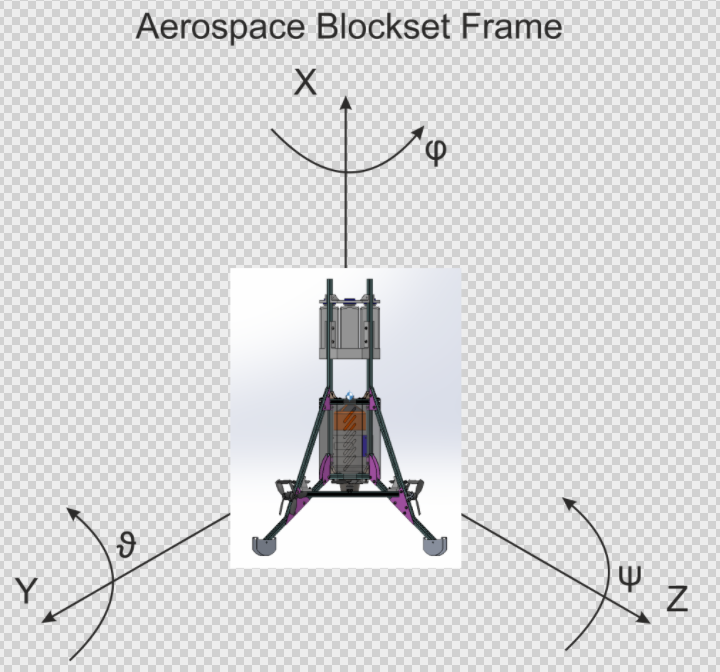 Hopper's Body Frame

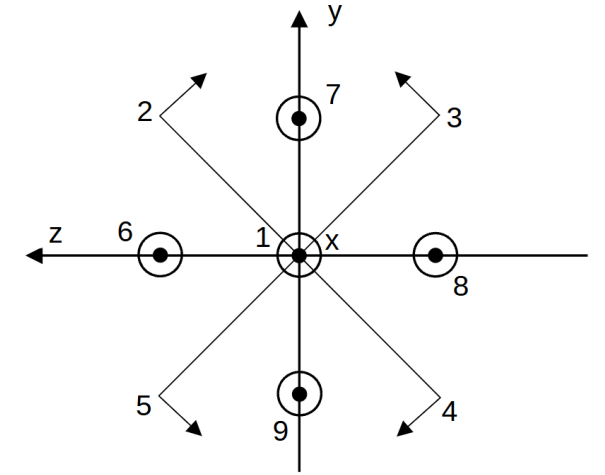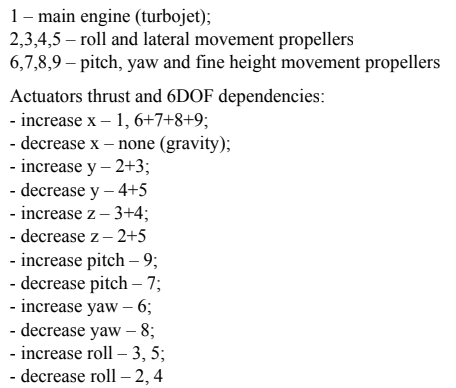

Hopper's Forces of Actuators Distribution

sq2 = 1 / sqrt(2);
% Force distrubution matrix
%     F1 F2     F3     F4    F5 F6 F7 F8 F9
Hf = [1, 0,     0,      0,    0, 1, 1, 1, 1;    % Fx
      0, sq2,   sq2, -sq2, -sq2, 0, 0, 0, 0;    % Fy
      0, -sq2,  sq2,  sq2, -sq2, 0, 0, 0, 0];   % Fz

% Lever matrix
%     F1 F2 F3  F4 F5 F6 F7  F8 F9
Hm = [0, -h, h, -h, h, 0, 0,  0, 0;
      0,  0, 0,  0, 0, d, 0, -d, 0;
      0,  0, 0,  0, 0, 0, -d, 0, d];

%      F1  F2    F3   F4   F5   F6   F7   F8   F9
Hm2 = [h_1, h_2, h_3, h_4,  0,   0,   0,    0,   0;
      0,    0,   0,   0,   h_5, 0,  -h_7,  0,   0;
      0,    0,   0,   0,   0,   h_6, 0,  -h_8,  0];

% Force vector
Fc = [F_1; F_2; F_3; F_4; F_5; F_6; F_7; F_8; F_9];
Fv = Hf * Fc;
Mv = Hm * Fc;
g = [g_x; g_y; g_z];
syms G;
gg = [0; -G; 0];

Lw([phi, theta, psi])

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & \sin\left(\theta \right) & -\psi \\ -\sin\left(\theta \right) & \cos\left(\theta \right) & \varphi \\ \varphi \,\sin\left(\theta \right) & \psi \,\sin\left(\theta \right)-\varphi \,\cos\left(\theta \right) & 1 \end{array}\right)$$

Lw([phi, pi/2, psi])

$$ans = \left(\begin{array}{ccc} 0 & 1 & -\psi \\ -1 & 0 & \varphi \\ \varphi & \psi & 1 \end{array}\right)$$

Lw([phi, pi/2, psi]) * gg

$$ans = \left(\begin{array}{c} -G\\ 0\\ -G\,\psi \end{array}\right)$$

Force Matrices

Fv

$$Fv = \left(\begin{array}{c} F_{1}+F_{6}+F_{7}+F_{8}+F_{9}\\ \frac{\sqrt{2}\,F_{2}}{2}+\frac{\sqrt{2}\,F_{3}}{2}-\frac{\sqrt{2}\,F_{4}}{2}-\frac{\sqrt{2}\,F_{5}}{2}\\ \frac{\sqrt{2}\,F_{3}}{2}-\frac{\sqrt{2}\,F_{2}}{2}+\frac{\sqrt{2}\,F_{4}}{2}-\frac{\sqrt{2}\,F_{5}}{2} \end{array}\right)$$

Mv

$$Mv = \left(\begin{array}{c} F_{3}\,h-F_{2}\,h-F_{4}\,h+F_{5}\,h\\ F_{6}\,d-F_{8}\,d\\ F_{9}\,d-F_{7}\,d \end{array}\right)$$

## Linear system. Plant

### Translational matrix A

Mass = diag([m, m, m]);
Massinv = inv(Mass);
A11 = zeros(3,3);
A12 = eye(3,3);
A21 = zeros(3,3);
A22 = -skew(w) + Mass \ (-Cv); % + Nrot * G; for linear system exclude gravity

At = [A11, A12;
      A21, A22]

$$At = \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & -\frac{c_{x}}{m} & w_{z} & -w_{y}\\ 0 & 0 & 0 & -w_{z} & -\frac{c_{y}}{m} & w_{x}\\ 0 & 0 & 0 & w_{y} & -w_{x} & -\frac{c_{z}}{m} \end{array}\right)$$

### Rotational Matrix A

A33 = zeros(4,4);
A43 = zeros(3,4);
A34 = QM(q);
% A44 = Jsinv * (-skew(w) * diag(Js*w) - Cw); % incorrect
A44 = Js \ (-skew(w) * Js - Cw);
Ar = [A33, A34;
      A43, A44];
Ar

$$Ar = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & -q_{1} & -q_{2} & -q_{3}\\ 0 & 0 & 0 & 0 & q_{0} & -q_{3} & q_{2}\\ 0 & 0 & 0 & 0 & q_{3} & q_{0} & -q_{1}\\ 0 & 0 & 0 & 0 & -q_{2} & q_{1} & q_{0}\\ 0 & 0 & 0 & 0 & -\frac{c_{r}}{J_{\mathrm{xx}}} & \frac{J_{\mathrm{yy}}\,w_{z}}{J_{\mathrm{xx}}} & -\frac{J_{\mathrm{zz}}\,w_{y}}{J_{\mathrm{xx}}}\\ 0 & 0 & 0 & 0 & -\frac{J_{\mathrm{xx}}\,w_{z}}{J_{\mathrm{yy}}} & -\frac{c_{p}}{J_{\mathrm{yy}}} & \frac{J_{\mathrm{zz}}\,w_{x}}{J_{\mathrm{yy}}}\\ 0 & 0 & 0 & 0 & \frac{J_{\mathrm{xx}}\,w_{y}}{J_{\mathrm{zz}}} & -\frac{J_{\mathrm{yy}}\,w_{x}}{J_{\mathrm{zz}}} & -\frac{c_{q}}{J_{\mathrm{zz}}} \end{array}\right)$$

### Full Dynamic Matrix A

As = [At, zeros(6,7);
     zeros(7,6), Ar]

$$As = \left(\begin{array}{ccccccccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -\frac{c_{x}}{m} & w_{z} & -w_{y} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -w_{z} & -\frac{c_{y}}{m} & w_{x} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & w_{y} & -w_{x} & -\frac{c_{z}}{m} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -q_{1} & -q_{2} & -q_{3}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & q_{0} & -q_{3} & q_{2}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & q_{3} & q_{0} & -q_{1}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -q_{2} & q_{1} & q_{0}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\frac{c_{r}}{J_{\mathrm{xx}}} & \frac{J_{\mathrm{yy}}\,w_{z}}{J_{\mathrm{xx}}} & -\frac{J_{\mathrm{zz}}\,w_{y}}{J_{\mathrm{xx}}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\frac{J_{\mathrm{xx}}\,w_{z}}{J_{\mathrm{yy}}} & -\frac{c_{p}}{J_{\mathrm{yy}}} & \frac{J_{\mathrm{zz}}\,w_{x}}{J_{\mathrm{yy}}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{J_{\mathrm{xx}}\,w_{y}}{J_{\mathrm{zz}}} & -\frac{J_{\mathrm{yy}}\,w_{x}}{J_{\mathrm{zz}}} & -\frac{c_{q}}{J_{\mathrm{zz}}} \end{array}\right)$$

### Control Matrix B

#### Translational matrix B

B11 = zeros(3, 9);
B21 = Mass \ Hf;
Bt = [B11;
      B21];
Bt

$$Bt = \begin{array}{l} \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ \frac{1}{m} & 0 & 0 & 0 & 0 & \frac{1}{m} & \frac{1}{m} & \frac{1}{m} & \frac{1}{m}\\ 0 & \sigma_{1} & \sigma_{1} & -\sigma_{1} & -\sigma_{1} & 0 & 0 & 0 & 0\\ 0 & -\sigma_{1} & \sigma_{1} & \sigma_{1} & -\sigma_{1} & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}}{2\,m} \end{array}$$

#### Rotational Matrix B

B31 = zeros(4,9);
% B41 = zeros(3,3);
B41 = Jsinv * Hm;
Br = [B31;
      B41];
Br

$$Br = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{h}{J_{\mathrm{xx}}} & \frac{h}{J_{\mathrm{xx}}} & -\frac{h}{J_{\mathrm{xx}}} & \frac{h}{J_{\mathrm{xx}}} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{d}{J_{\mathrm{yy}}} & 0 & -\frac{d}{J_{\mathrm{yy}}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{d}{J_{\mathrm{zz}}} & 0 & \frac{d}{J_{\mathrm{zz}}} \end{array}\right)$$

#### Full Control Matrix B

Bs = [Bt; Br]

$$Bs = \begin{array}{l} \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ \frac{1}{m} & 0 & 0 & 0 & 0 & \frac{1}{m} & \frac{1}{m} & \frac{1}{m} & \frac{1}{m}\\ 0 & \sigma_{1} & \sigma_{1} & -\sigma_{1} & -\sigma_{1} & 0 & 0 & 0 & 0\\ 0 & -\sigma_{1} & \sigma_{1} & \sigma_{1} & -\sigma_{1} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & -\frac{h}{J_{\mathrm{xx}}} & \frac{h}{J_{\mathrm{xx}}} & -\frac{h}{J_{\mathrm{xx}}} & \frac{h}{J_{\mathrm{xx}}} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{d}{J_{\mathrm{yy}}} & 0 & -\frac{d}{J_{\mathrm{yy}}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -\frac{d}{J_{\mathrm{zz}}} & 0 & \frac{d}{J_{\mathrm{zz}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}}{2\,m} \end{array}$$

GG = Nw([phi, theta, psi]) * gg

$$GG = \left(\begin{array}{c} -G\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ -G\,\left(\cos\left(\varphi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\\ G\,\left(\cos\left(\theta \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right) \end{array}\right)$$

LNw = [diff(GG, phi), diff(GG, theta), diff(GG, psi)]

$$LNw = \left(\begin{array}{ccc} 0 & -G\,\cos\left(\psi \right)\,\cos\left(\theta \right) & G\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ G\,\left(\cos\left(\theta \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right) & G\,\left(\cos\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)\right) & -G\,\cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ G\,\left(\cos\left(\varphi \right)\,\cos\left(\theta \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right) & -G\,\left(\sin\left(\varphi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right)\right) & -G\,\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) \end{array}\right)$$

 LL = [diff(Nw([phi, theta, psi]), phi), diff(Nw([phi, theta, psi]), theta), diff(Nw([phi, theta, psi]), psi)]

$$LL = \begin{array}{l} \left(\begin{array}{ccccccccc} 0 & 0 & 0 & -\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) & 0 & -\cos\left(\theta \right)\,\sin\left(\psi \right) & -\sin\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\psi \right)\\ \sigma_{2} & \sigma_{4}-\sigma_{5} & \cos\left(\varphi \right)\,\cos\left(\psi \right) & \sigma_{1} & \sigma_{3}-\sigma_{6} & 0 & \cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & -\sin\left(\varphi \right)\,\sin\left(\psi \right)\\ \sigma_{6}-\sigma_{3} & \sigma_{1} & -\cos\left(\psi \right)\,\sin\left(\varphi \right) & \sigma_{5}-\sigma_{4} & \sigma_{2} & 0 & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\psi \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\varphi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\sin\left(\varphi \right)\,\sin\left(\theta \right)+\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sigma_{3}=\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right)\\ \sigma_{4}=\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{5}=\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sigma_{6}=\cos\left(\varphi \right)\,\sin\left(\theta \right) \end{array}$$

LL = [diff(Nw([phi, pi/2, psi]), phi), diff(Nw([phi, pi/2, psi]), theta), diff(Nw([phi, pi/2, psi]), psi)]

$$LL = \begin{array}{l} \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\sin\left(\psi \right) & -\cos\left(\psi \right)\\ \sin\left(\varphi \right) & \sigma_{3} & \sigma_{4} & 0 & 0 & 0 & 0 & \sigma_{2} & \sigma_{1}\\ \cos\left(\varphi \right) & \sigma_{1} & -\sigma_{2} & 0 & 0 & 0 & 0 & \sigma_{4} & -\sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sin\left(\varphi \right)\,\sin\left(\psi \right)\\ \sigma_{2}=\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ \sigma_{3}=\cos\left(\varphi \right)\,\sin\left(\psi \right)\\ \sigma_{4}=\cos\left(\varphi \right)\,\cos\left(\psi \right) \end{array}$$